**Transient Diffusion-Reaction-Kinetic Model for Carbon Dioxide Electrolysis**

T           =20 ; % temperature [degC]
P           =1 ; % pressure [bar]
n_CO        =0.5; % CO Faradaic efficiency [-]
n_iHCOO     =0; % HCOO(-) Faradaic efficiency [-]
n_CH4       =0; % CH4 Faradaic efficiency [-]
n_C2H4      =0; % C2H4 Faradaic efficiency [-]
n           = [n_CO n_iHCOO n_CH4 n_C2H4];

electrolyte = "KHCO3"      ;
c           =100; % concentration of electrolyte [mM]
L           =50; % diffusion boundary layer length [um]

Enter the current density of interest or enter a range of current densities to calculate a polarization curve:

j           =     -10  ; % current density [mA/cm2]
%j           = [-1:-1:-20];             ; % array of current density [mA/cm2]

Enter kinetic parameters (set exchange current density to zero to ignore that product):

j_0_H2      = 0.003      ; % exchange current density H2 [mA/cm2]
a_H2        =0.18; % charge transfer coefficient H2 [-]
j_0_CO      = 0.0004      ; % exchange current density CO [mA/cm2]
a_CO        =0.48; % charge transfer coefficient CO [-]
j_0_C2H4    = 0      ; % exchange current density C2H4 [mA/cm2]
a_C2H4      =0; % charge transfer coefficient C2H4 [-]
j_0         = [j_0_H2 j_0_CO 0 0 j_0_C2H4];
a           = [a_H2 a_CO 0 0 a_C2H4];

Additional parameters for the numerical modelling algorithm:

n_x         = 200;        % number of grid points - 1 (must be even-numbered)
t           = 10;        % total time of simulation [s]
dt          = 1;        % time step size [s]
C           = 0.01;        % convergence criterion [-]
iter_max    = 10;   % maximum iterations for convergence [-]
lambda      = 1; % relaxation parameter (between 0-1) [-]
simplified  = false;                         % ignore volumetric reaction terms that are small

Hit the button below when settings are as desired:

***1D Transient Diffusion-Reaction-Kinetic Model for a Planar Electrode***


---PART I: Thermodynamic and Kinetic Parameters---

Thermodynamic state of the system:
	 T = 293.15 K
	 P = 1.00 bar
	 c = 100.00 mol/m3 KHCO3
	 u = 1.01 mPa s (based on salt molarity and temperature)
	 p = 1004.6 kg/m3 (based on salt molarity)
Solubility of CO2 in equilibrium with 1.00 bar pure CO2 atmosphere:
	 37.9 mM (Henry Law)	 --->	 36.5 mM (Sechenov)
Diffusion coefficients of species in the diffusion layer:
	 D(CO2)     = 1.649e-09 m2/s
	 D(HCO3(-)) = 1.023e-09 m2/s
	 D(CO3(2-)) = 7.967e-10 m2/s
	 D(OH(-))   = 4.552e-09 m2/s
	 D(H(+))    = 8.037e-09 m2/s
Corrected for temperature and viscosity.

Self-ionization constant of water:
	 Kw         = 6.840e-15 M2 (pKw = -log(Kw) = 14.16)
Note that this is only corrected for temperature, not ionic strength.Equilibrium coefficients:
	 Ka1        = [HCO3(-)][H(+)] /[CO2]     = 7.606e-07 M (pKa1 = 6.12)
	 Ka2        = [CO3(2-)][H(+)] /[HCO3(-)] = 2.661e-10 M (pK

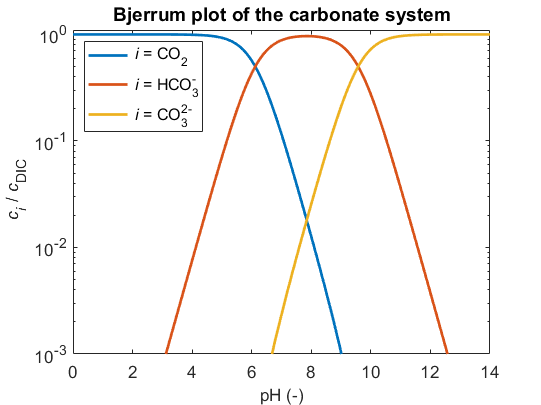


The fraction of CO2/HCO3(-)/CO3(2-) of the Dissolved Inorganic Content (DIC) as a function of pH.

The initial conditions of the CO2-saturated electrolyte are:
	CO2     36.50502 mM
	OH(-)   0.00002 mM
	HCO3(-) 99.80928 mM
	CO3(2-) 0.09549 mM
	H(+)    0.00028 mM
	pH      6.56 

The standard state equilibrium potential at T = 298.15 K and T = 293 K:
	E_0_H2        0.000 V_SHE	 E_H2        0.001 V_SHE
	E_0_CO        -0.104 V_SHE	 E_CO        -0.101 V_SHE
	E_0_HCOO(-)   0.378 V_SHE	 E_HCOO(-)   0.378 V_SHE
	E_0_CH4       0.169 V_SHE	 E_CH4       0.169 V_SHE
	E_0_C2H4      0.079 V_SHE	 E_C2H4      0.079 V_SHE
	E_0_C2H5OH    0.084 V_SHE	 E_C2H5OH    0.084 V_SHE
	E_0_CH3COO(-) 0.150 V_SHE	 E_CH3COO(-) 0.150 V_SHE

The Nernstian equilibrium potential at T = 293 K and corrected for electrolyte concentrations:
	E_OCP_H2        -0.381 V_SHE
	E_OCP_CO        -0.524 V_SHE
	E_OCP_HCOO(-)   0.146 V_SHE
	E_OCP_CH4       -0.223 V_SHE
	E_OCP_C2H4      -0.316 V_SHE
	E_OCP_C2H5OH    -0.311 V_SHE
	E_OCP_C

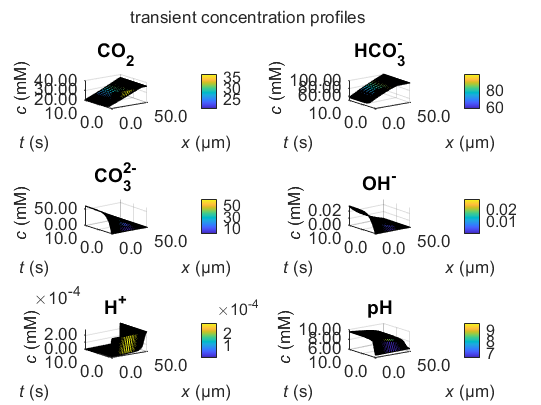

Transients upon imposing -10.0 mA/cm2 at the cathode.


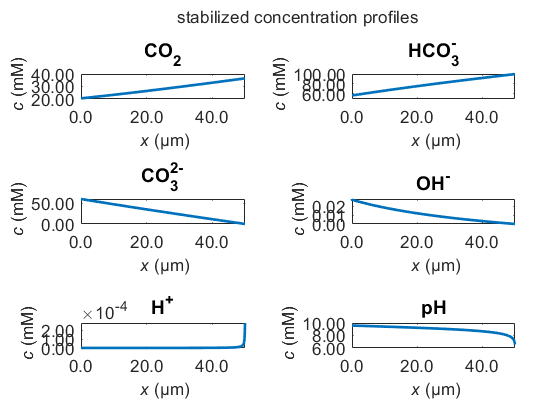

The profiles 10.0 s after imposing -10.0 mA/cm2 at the cathode.

Concentrations at the cathode surface after equilibration:
	CO2     20.52338 mM
	HCO3(-) 57.02755 mM
	CO3(2-) 59.96997 mM
	OH(-)   0.0278547197 mM
	H(+)    0.0000002533 mM
	pH      9.60   


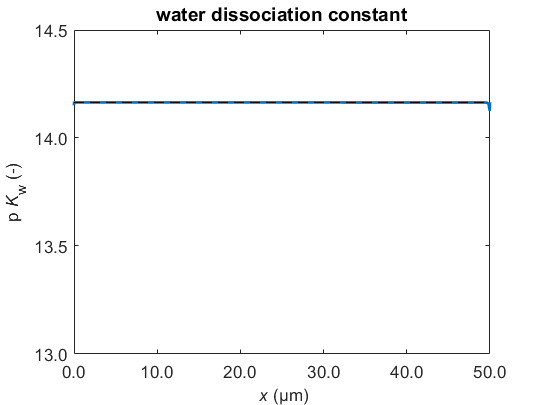

The calculated water dissociation constant compared to the theoretical value (dashed).


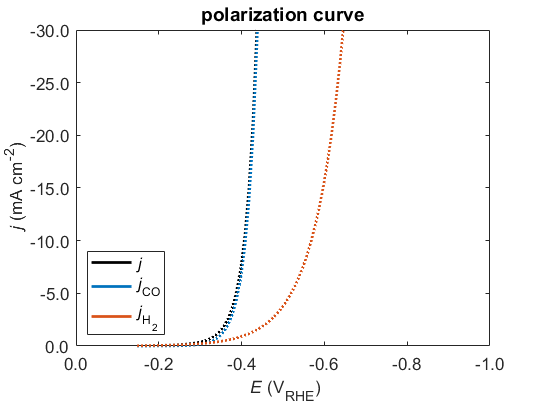

Polarization curves in absence (dashed) and presence (solid) of mass transport limitations.


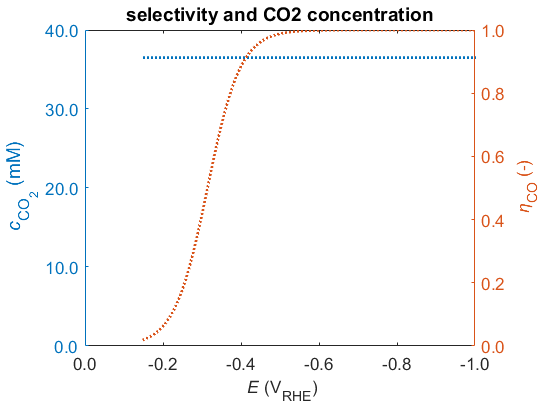

For each current density input, FE and CO2 concentration at the cathode surface are shown in absence (dashed) and presence (solid) of mass transport limitations.

Elapsed time for PART IV is 0.987 seconds.


***Total elapsed time for this script is 40.063 seconds.***

 
% make call to model script using above parameters
tdrk_model(T,P,j,n,electrolyte,c,L,j_0,a,n_x,t,dt,C,iter_max,lambda,simplified);